# Test all the scripts by running them here

The CreateLetterDatasetInstances and the live scripts can all be run independently. None of them save mat data. Some live scripts do generate csv result files which are present in the Results folder. When running this script the **current folder in MATLAB should be Results** so that the results csv's generated replace those already present. **The folders and subfolders of Code, Dataset and Results should be added to the MATLAB path prior to running this live script**.

**Running this live script takes several hours**: it is used to test that all the code works.

## Script descriptions

**CreateLetterDatasetInstances (script)**: Tests that the "letter-recognition.csv" dataset is read into the LetterDatasetClass three times, to create 3 instances: original data, normalised (using z-score), normalised and with highly correlated features removed.

**DatasetAnalysis (livescript)**: runs correlation analysis on the dataset class instances loaded.

**TestLetterDecisionTree (livescript)**: performs hyperparameter search of the decision tree method. Creates a final decision tree instance model.

**testNBayes (livescript)**: performs a first pass at hyperparameter search using the Naive Bayes method. The search is done on the original dataset, normalised dataset and the dataset with features removed.

**testNBayes2 (livescript)**: performs a detailed hyperparameter search on the 3 datasets, and creates the final Naive Bayes instance model.

**TestRandomForest (livescript)**: performs a detailed hyperparameter search on the 3 datasets, and creates the final Random Forest instance model.

**FinalModelComparison (livescript)**: performs the final peerformance comparison using the 3 methods on the normalised dataset with highly correlated features removed.

## MATLAB code

### CreateLetterDatasetInstances

fprintf("Running CreateLetterDatasetInstances\n");

Running CreateLetterDatasetInstances


CreateLetterDatasetInstances



Dataset information (~normalised):
  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 0
          isRemovedFeature: 0

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min           0   
            Median        4   
            Max          15   

    yBox: 16000×1 double

        Values:

            Min           0   
  

fprintf("Done\n");

Done


### DatasetAnalysis

fprintf("Running DatasetAnalysis\n");

Running DatasetAnalysis


Summary of letter distribution:
Minimum examples per class: 577
Maximum examples per class: 661
Median number of examples per class: 613.5000


  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 0
          isRemovedFeature: 0

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min           0   
            Median        4   
            Max          15   

    yBox: 16000×1 double

        Values:

            Min           0   
            Median        7   
            Max          15 

Summary of letter distribution:
Minimum examples per class: 577
Maximum examples per class: 661
Median number of examples per class: 613.5000


  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 1
          isRemovedFeature: 0

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min         -2.1101
            Median    -0.015025
            Max          5.7463

    yBox: 16000×1 double

        Values:

            Min          -2.138
            Median    -0.012053
            Max        

Summary of letter distribution:
Minimum examples per class: 577
Maximum examples per class: 661
Median number of examples per class: 613.5000


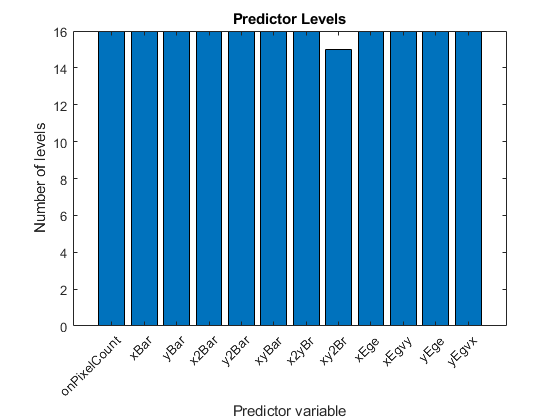

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    onPixelCount: 16000×1 double

        Values:

            Min        -1.6025
            Median    -0.23125
            Max         5.2537

    xBar: 16000×1 double

        Values:

            Min        -3.3985
            Median    0.054728
            Max     

DatasetAnalysis

fprintf("Done\n");

Done


### TestLetterDecisionTree

fprintf("Running TestLetterDecisionTree\n");

Running TestLetterDecisionTree


Starting decision tree analysis...
Completed decision tree analysis
Starting decision tree analysis...
Completed decision tree analysis
    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

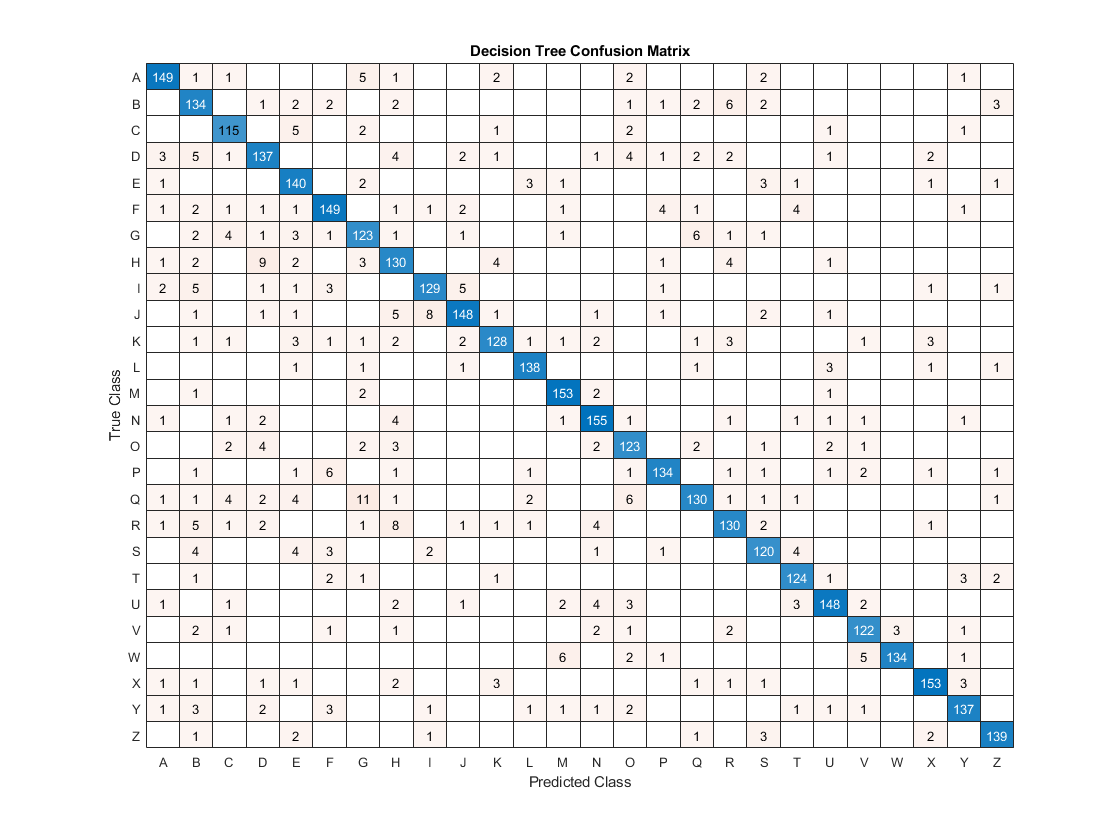

    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime
    ___________    ____________    _________    ______    __________    ___________    ___________

      0.8805          0.8811        0.8821      0.8816       4000         0.3906         0.0156   



TestLetterDecisionTree

fprintf("Done\n");

Done


### testNBayes

fprintf("Running testNBayes\n");

Running testNBayes


ans =     0.0391    0.0381    0.0381    0.0399    0.0384    0.0378    0.0393    0.0361    0.0379    0.0361    0.0367    0.0384    0.0396    0.0383    0.0382    0.0407    0.0386    0.0375    0.0381    0.0413    0.0404    0.0393    0.0377    0.0387    0.0394    0.0366


ans =     0.0413    0.0379    0.0399    0.0383    0.0393    0.0391    0.0396    0.0387    0.0382    0.0375    0.0381    0.0361    0.0381    0.0361    0.0384    0.0381    0.0384    0.0394    0.0386    0.0407    0.0393    0.0377    0.0404    0.0378    0.0366    0.0368


Default Training Loss:   0.3539 Test Loss 0.3668
Empirical Training Loss: 0.3549 Test Loss 0.3678
  Columns 1 through 6

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 7 through 12

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 13 through 16

    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×16 table]
                      y: [16000×1 table]
                     xt: [4000×16 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×16 cell}
        distNamesKernel: {1×16 cell}
              sm

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33776 |      69.749 |     0.33776 |     0.33776 |       kernel |        1.287 |


|    2 | Accept |     0.35793 |     0.57891 |     0.33776 |     0.34745 |       normal |            - |


|    3 | Accept |     0.35793 |     0.47244 |     0.33776 |     0.33776 |       normal |            - |


|    4 | Accept |     0.51687 |      72.208 |     0.33776 |     0.33777 |       kernel |       8.6162 |


|    5 | Best   |     0.24992 |      41.425 |     0.24992 |     0.24993 |       kernel |      0.30805 |


|    6 | Best   |     0.24938 |      41.629 |     0.24938 |     0.24934 |       kernel |      0.25009 |


|    7 | Accept |     0.24938 |       41.28 |     0.24938 |     0.24936 |       kernel |      0.25013 |


|    8 | Accept |     0.24971 |      41.424 |     0.24938 |      0.2494 |       kernel |      0.27016 |


|    9 | Accept |     0.24938 |       41.36 |     0.24938 |     0.24939 |       kernel |      0.25017 |


|   10 | Accept |     0.24971 |        41.5 |     0.24938 |     0.24946 |       kernel |      0.26968 |


|   11 | Accept |     0.24938 |      42.004 |     0.24938 |     0.24945 |       kernel |      0.25021 |


|   12 | Accept |     0.63389 |      69.793 |     0.24938 |     0.24947 |       kernel |       14.999 |


|   13 | Accept |     0.25828 |      41.832 |     0.24938 |     0.24947 |       kernel |      0.45363 |


|   14 | Accept |     0.24964 |      41.945 |     0.24938 |     0.24949 |       kernel |      0.28095 |


|   15 | Accept |     0.44594 |      71.892 |     0.24938 |     0.24949 |       kernel |        3.114 |


|   16 | Accept |     0.28749 |      61.961 |     0.24938 |      0.2495 |       kernel |      0.76843 |


|   17 | Accept |      0.4862 |      72.435 |     0.24938 |      0.2495 |       kernel |       5.0671 |


|   18 | Accept |     0.26841 |      53.686 |     0.24938 |     0.24949 |       kernel |      0.58156 |


|   19 | Accept |     0.39126 |      72.705 |     0.24938 |     0.24949 |       kernel |       1.9163 |


|   20 | Accept |     0.25278 |      41.659 |     0.24938 |     0.24949 |       kernel |      0.37164 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25073 |      41.744 |     0.24938 |     0.24948 |       kernel |      0.33456 |


|   22 | Accept |     0.30923 |      61.154 |     0.24938 |     0.24948 |       kernel |      0.97527 |


|   23 | Accept |     0.24995 |      41.997 |     0.24938 |     0.24951 |       kernel |      0.29221 |


|   24 | Accept |     0.24951 |      42.954 |     0.24938 |     0.24946 |       kernel |      0.25874 |


|   25 | Accept |     0.24951 |      42.108 |     0.24938 |     0.24947 |       kernel |      0.25768 |


|   26 | Accept |     0.24938 |      42.009 |     0.24938 |     0.24946 |       kernel |      0.25002 |


|   27 | Accept |     0.25474 |      41.494 |     0.24938 |     0.24946 |       kernel |      0.40781 |


|   28 | Accept |      0.5606 |      68.479 |     0.24938 |     0.24946 |       kernel |       11.666 |


|   29 | Accept |     0.42189 |      72.786 |     0.24938 |     0.24946 |       kernel |        2.444 |


|   30 | Accept |     0.24951 |      41.362 |     0.24938 |     0.24947 |       kernel |       0.2574 |


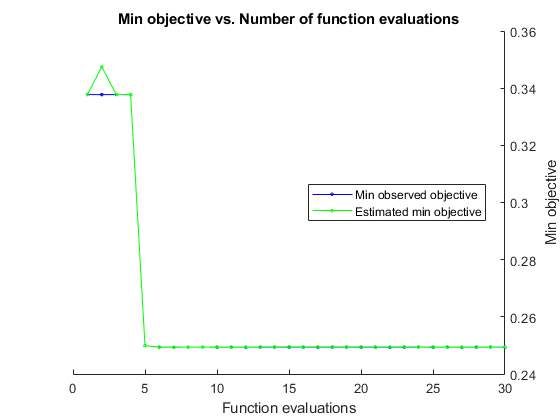

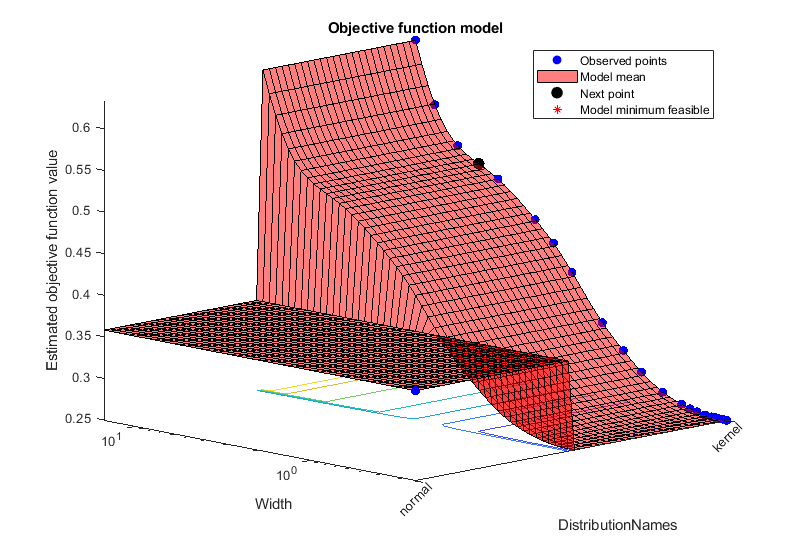


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1486.179 seconds
Total objective function evaluation time: 1457.6241

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25009

Observed objective function value = 0.24938
Estimated objective function value = 0.24945
Function evaluation time = 41.6291

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25768

Estimated objective function value = 0.24947
Estimated function evaluation time = 41.6219

Training loss: 0.2342 Test loss: 0.2508, normalised dataset: 0
Total cpu time (seconds, includes optimization search): 

startTime = 8.1377e+03

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33501 |      69.878 |     0.33501 |     0.33501 |       kernel |       0.5295 |


|    2 | Accept |     0.35793 |     0.43041 |     0.33501 |     0.34603 |       normal |            - |


|    3 | Accept |     0.35793 |     0.41307 |     0.33501 |     0.33501 |       normal |            - |


|    4 | Accept |     0.54537 |      69.661 |     0.33501 |     0.33502 |       kernel |       5.0418 |


|    5 | Best   |        0.25 |      26.458 |        0.25 |     0.25001 |       kernel |     0.097246 |


|    6 | Accept |     0.25531 |      44.815 |        0.25 |     0.24998 |       kernel |      0.16444 |


|    7 | Best   |     0.24994 |      25.658 |     0.24994 |     0.24971 |       kernel |     0.075972 |


|    8 | Accept |     0.25007 |      28.838 |     0.24994 |     0.24988 |       kernel |      0.09833 |


|    9 | Accept |     0.24994 |      25.516 |     0.24994 |     0.24988 |       kernel |     0.075985 |


|   10 | Accept |        0.25 |      25.481 |     0.24994 |     0.24988 |       kernel |     0.092734 |


|   11 | Accept |        0.25 |      25.552 |     0.24994 |      0.2499 |       kernel |     0.089785 |


|   12 | Accept |     0.24994 |      24.703 |     0.24994 |     0.24989 |       kernel |     0.075988 |


|   13 | Accept |     0.78637 |      71.686 |     0.24994 |     0.24998 |       kernel |       9.7236 |


|   14 | Accept |       0.464 |      72.993 |     0.24994 |     0.24995 |       kernel |       1.5011 |


|   15 | Accept |     0.27132 |      52.004 |     0.24994 |     0.24995 |       kernel |      0.25841 |


|   16 | Accept |     0.25033 |      35.132 |     0.24994 |     0.24997 |       kernel |      0.12027 |


|   17 | Accept |     0.24994 |      24.957 |     0.24994 |     0.24997 |       kernel |     0.084018 |


|   18 | Accept |     0.25019 |       32.25 |     0.24994 |     0.24997 |       kernel |       0.1097 |


|   19 | Accept |     0.24994 |       24.36 |     0.24994 |     0.24998 |       kernel |     0.075967 |


|   20 | Accept |     0.24994 |      24.803 |     0.24994 |     0.24998 |       kernel |     0.084334 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.50222 |      71.894 |     0.24994 |     0.24998 |       kernel |       2.7119 |


|   22 | Accept |     0.39413 |      72.016 |     0.24994 |     0.24997 |       kernel |       0.8542 |


|   23 | Accept |     0.29552 |      58.645 |     0.24994 |     0.24994 |       kernel |      0.35897 |


|   24 | Accept |     0.26091 |      44.773 |     0.24994 |     0.24994 |       kernel |      0.20397 |


|   25 | Accept |     0.25158 |      38.853 |     0.24994 |     0.24995 |       kernel |      0.14035 |


|   26 | Accept |     0.25096 |      37.457 |     0.24994 |     0.24995 |       kernel |      0.12933 |


|   27 | Accept |     0.24994 |       24.43 |     0.24994 |     0.24994 |       kernel |     0.079584 |


|   28 | Accept |     0.25014 |      29.173 |     0.24994 |     0.24994 |       kernel |      0.10389 |


|   29 | Accept |     0.63839 |      68.986 |     0.24994 |     0.24994 |       kernel |       7.0072 |


|   30 | Accept |     0.25026 |       34.39 |     0.24994 |     0.24994 |       kernel |      0.11443 |


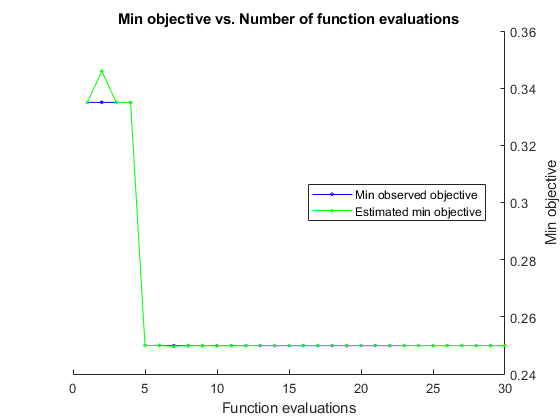

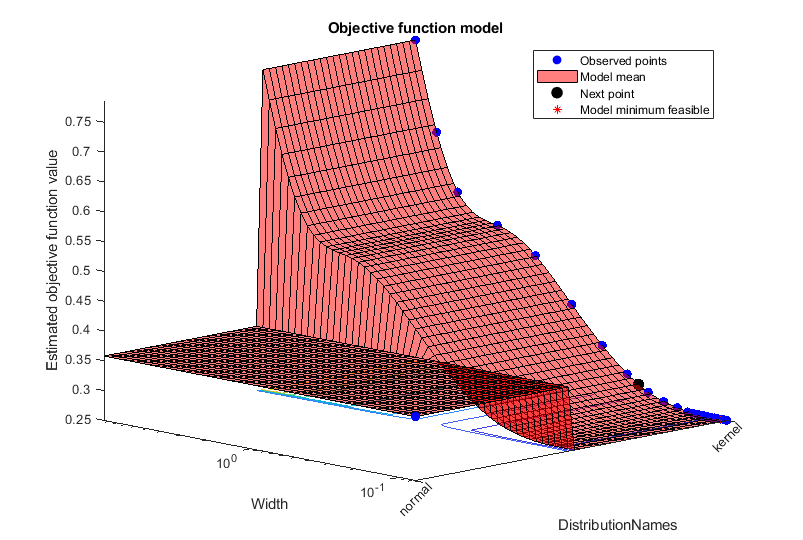


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1209.6242 seconds
Total objective function evaluation time: 1186.2056

Best observed feasible point:
    DistributionNames     Width  
    _________________    ________

         kernel          0.075972

Observed objective function value = 0.24994
Estimated objective function value = 0.24996
Function evaluation time = 25.6575

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.079584

Estimated objective function value = 0.24994
Estimated function evaluation time = 24.8437

Training loss: 0.2338 Test loss: 0.2520, normalised dataset: 1
Total cpu time (seconds, includes optimization se

letterDataset =   LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {'onPixelCount'  'xBar'  'yBar'  'x2Bar'  'y2Bar'  'xyBar'  'x2yBr'  'xy2Br'  'xEge'  'xEgvy'  'yEge'  'yEgvx'}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1


Training loss: 0.3059 Test loss: 0.3123, selected features, normalised dataset: 1
Total cpu time (seconds): 427.7813  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×12 table]
                      y: [16000×1 table]
                     xt: [4000×12 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×12 cell}
        distNamesKernel: {1×12 cell}
              smoothBox: {1×12 cell}
     smoothEpanechnikov: {1×12 cell}
           smoothNormal: {1×12 cell}
         smoothTriangle: {1×12 cell}
          smoothUnsused: {1×16 cell}



|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33719 |      53.122 |     0.33719 |     0.33719 |       kernel |      0.59875 |


|    2 | Accept |     0.34912 |      0.4004 |     0.33719 |     0.34292 |       normal |            - |


|    3 | Accept |     0.34912 |      0.4067 |     0.33719 |     0.33719 |       normal |            - |


|    4 | Accept |     0.52983 |      55.231 |     0.33719 |      0.3372 |       kernel |       5.1836 |


|    5 | Best   |     0.24797 |      19.171 |     0.24797 |     0.24798 |       kernel |       0.0932 |


|    6 | Accept |     0.24797 |      19.297 |     0.24797 |     0.24797 |       kernel |     0.094061 |


|    7 | Accept |     0.25189 |      30.345 |     0.24797 |     0.24793 |       kernel |      0.16072 |


|    8 | Accept |     0.24817 |      25.405 |     0.24797 |       0.248 |       kernel |      0.11358 |


|    9 | Accept |     0.24811 |      25.461 |     0.24797 |     0.24793 |       kernel |      0.10824 |


|   10 | Accept |     0.24816 |       23.02 |     0.24797 |     0.24797 |       kernel |      0.10635 |


|   11 | Accept |     0.24797 |      19.237 |     0.24797 |     0.24797 |       kernel |     0.093284 |


|   12 | Accept |     0.78746 |      50.036 |     0.24797 |     0.24799 |       kernel |       9.7261 |


|   13 | Accept |     0.45887 |      54.484 |     0.24797 |     0.24798 |       kernel |       1.6695 |


|   14 | Accept |     0.26886 |       38.87 |     0.24797 |     0.24798 |       kernel |      0.28281 |


|   15 | Accept |     0.24905 |      29.715 |     0.24797 |     0.24798 |       kernel |      0.12827 |


|   16 | Accept |     0.24804 |      22.081 |     0.24797 |     0.24796 |       kernel |       0.1013 |


|   17 | Accept |     0.24797 |      19.111 |     0.24797 |     0.24798 |       kernel |      0.09336 |


|   18 | Accept |     0.49202 |      53.702 |     0.24797 |     0.24798 |       kernel |       2.9031 |


|   19 | Accept |     0.24797 |      22.489 |     0.24797 |     0.24796 |       kernel |      0.10116 |


|   20 | Accept |     0.24797 |      19.319 |     0.24797 |     0.24798 |       kernel |     0.093208 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.39346 |      53.349 |     0.24797 |     0.24798 |       kernel |      0.96055 |


|   22 | Accept |     0.29389 |      47.337 |     0.24797 |     0.24798 |       kernel |      0.39991 |


|   23 | Accept |     0.25739 |      35.042 |     0.24797 |     0.24798 |       kernel |        0.214 |


|   24 | Accept |     0.25437 |      31.336 |     0.24797 |     0.24798 |       kernel |      0.18488 |


|   25 | Accept |     0.25022 |      29.271 |     0.24797 |     0.24798 |       kernel |      0.14282 |


|   26 | Accept |     0.28025 |      43.564 |     0.24797 |     0.24798 |       kernel |      0.33362 |


|   27 | Accept |     0.62905 |      55.042 |     0.24797 |     0.24796 |       kernel |       7.0916 |


|   28 | Accept |     0.26141 |      38.072 |     0.24797 |     0.24796 |       kernel |      0.24318 |


|   29 | Accept |     0.24836 |       26.39 |     0.24797 |     0.24795 |       kernel |      0.11971 |


|   30 | Accept |     0.43002 |       53.68 |     0.24797 |     0.24795 |       kernel |        1.252 |


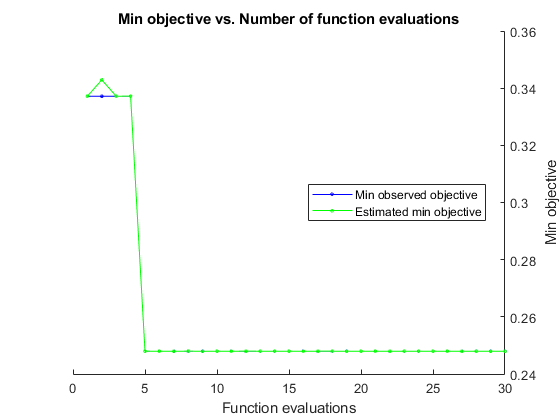

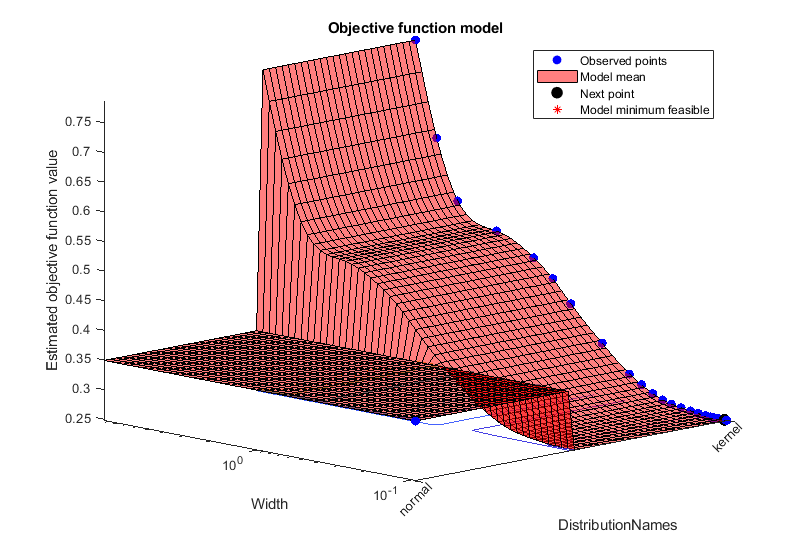


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1016.9009 seconds
Total objective function evaluation time: 993.9858

Best observed feasible point:
    DistributionNames    Width 
    _________________    ______

         kernel          0.0932

Observed objective function value = 0.24797
Estimated objective function value = 0.248
Function evaluation time = 19.1711

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.10116

Estimated objective function value = 0.24795
Estimated function evaluation time = 22.0068

Training loss: 0.2350 Test loss: 0.2502, selected features, normalised dataset: 1
Total cpu time (seconds, includes optimiza

testNBayes

fprintf("Done\n");

Done


### testNBayes2

fprintf("Running testNBayes2\n");

Running testNBayes2


  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1

Starting Naive Bayes analysis...
Completed NBayes analysis
Total cpu time (seconds): 10.9063    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1

Starting Naive Bayes analysis...
Completed NBayes analysis
Total cpu time (seconds): 2886.9688    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________


    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}    0.18           5                  6              0.24

bestTriangle = 1×14 table
    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}    0.11           2           

Starting Naive Bayes analysis...
Completed NBayes analysis
Total cpu time (seconds): 6630.4375    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________


    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}     0.11           2                 13              0.23

bestNormal = 1×14 table
    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}     0.11           2             

Starting Naive Bayes analysis...
Completed NBayes analysis
Total cpu time (seconds): 1955.2031    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________</

    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}    0.18           5                  6      

bestEpanechnikov = 1×14 table
    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}    0.11       

Starting Naive Bayes analysis...
Completed NBayes analysis
Total cpu time (seconds): 1689.5938    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________


    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}       0.18           5                  6              0.23

bestBox = 1×14 table
    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}       0.11           2                

    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'    }    0.11           2                 13      

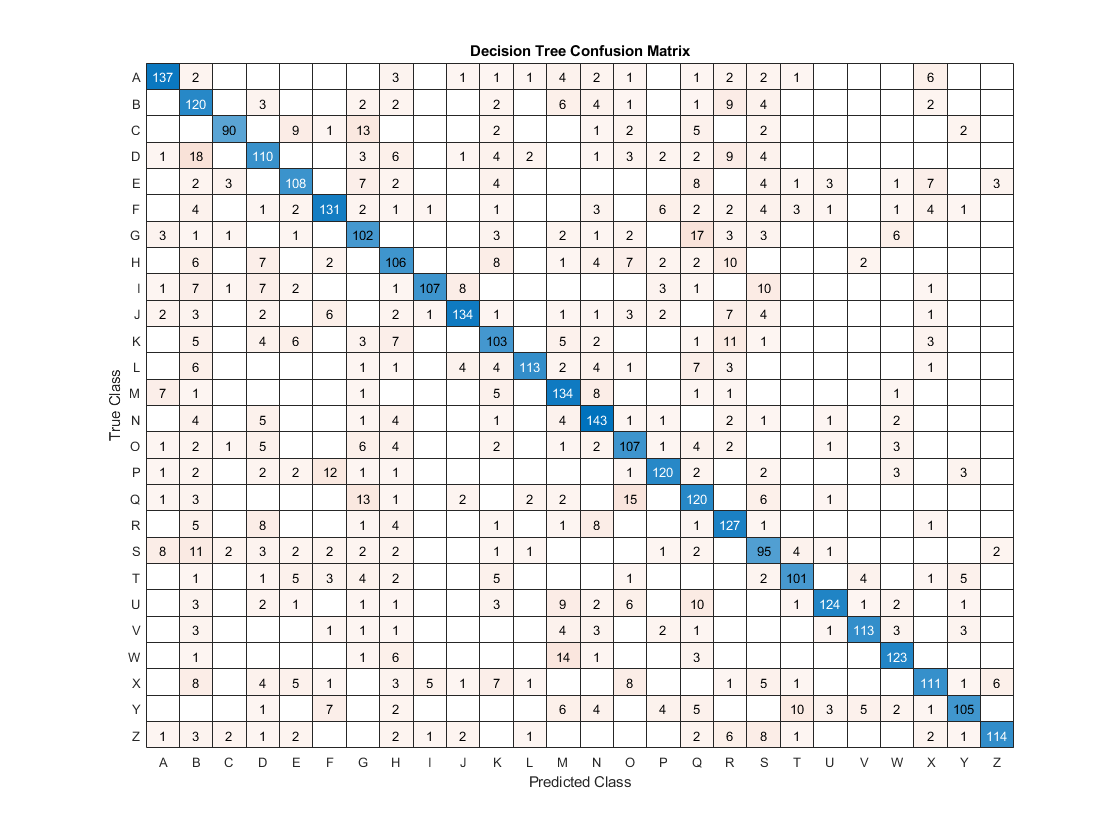

Accuracy: 0.7495 Precision: 0.7491 Recall: 0.7675 F1 0.7582. Train time: 1.6250 Predict time: 3.8594


testNBayes2

fprintf("Done\n");

Done


### TestRandomForest

fprintf("Running TestRandomForest\n");

Running TestRandomForest


  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1



rfHyperparameters =   RFHyperparameters with properties:

      features: [2 4]
         trees: 25
         folds: [2 3]
    randomSeed: 122


Starting Random Forest analysis...
Misclassified 179 entries out of 3200. 5.5938 pct	Training loss: 0.01. Test Loss: 0.09 Oob Error: 0.18	Precision: 0.9435 Recall: 0.9441 Accuracy: 0.9441 F1: 0.9438
	numTree 25 numFeature 2 trainErr 0.0100 testErr 0.0855 oobErr 0.1825 fold 1  of 2 predictTime 0.5156	Samples: T I D N G
Misclassified 164 entries out of 3200. 5.1250 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precision: 0.9482 Recall: 0.9488 Accuracy: 0.9487 F1: 0.9485
	numTree 25 numFeature 2 trainErr 0.0098 testErr 0.0824 oobErr 0.1839 fold 2  of 2 predictTime 0.6406	Samples: T I D N A
Misclassified 160 entries out of 3200. 5.0000 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.19	Precision: 0.9498 Recall: 0.9498 Accuracy: 0.9500 F1: 0.9498
	numTree 25 numFeature 2 trainErr 0.0107 testErr 0.0819 oobErr 0.1861 fold 1  of 3 predictTime 0.4219	Samples: T I G A M
Misclassified 142 entries out of 3200. 4.4375 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precisi

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       200       2             58               0.0011         0.0475         0.0658        0.9589          0.9585        0

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       200       2             58               0.0011         0.0475         0.0658        0.9589          0.9585        0

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       2       100       3             20                0.003         0.0558         0.0888        0.9571          0.9569        0

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       100       2             22               0.0022         0.0527         0.0847        0.9572          0.9563        0

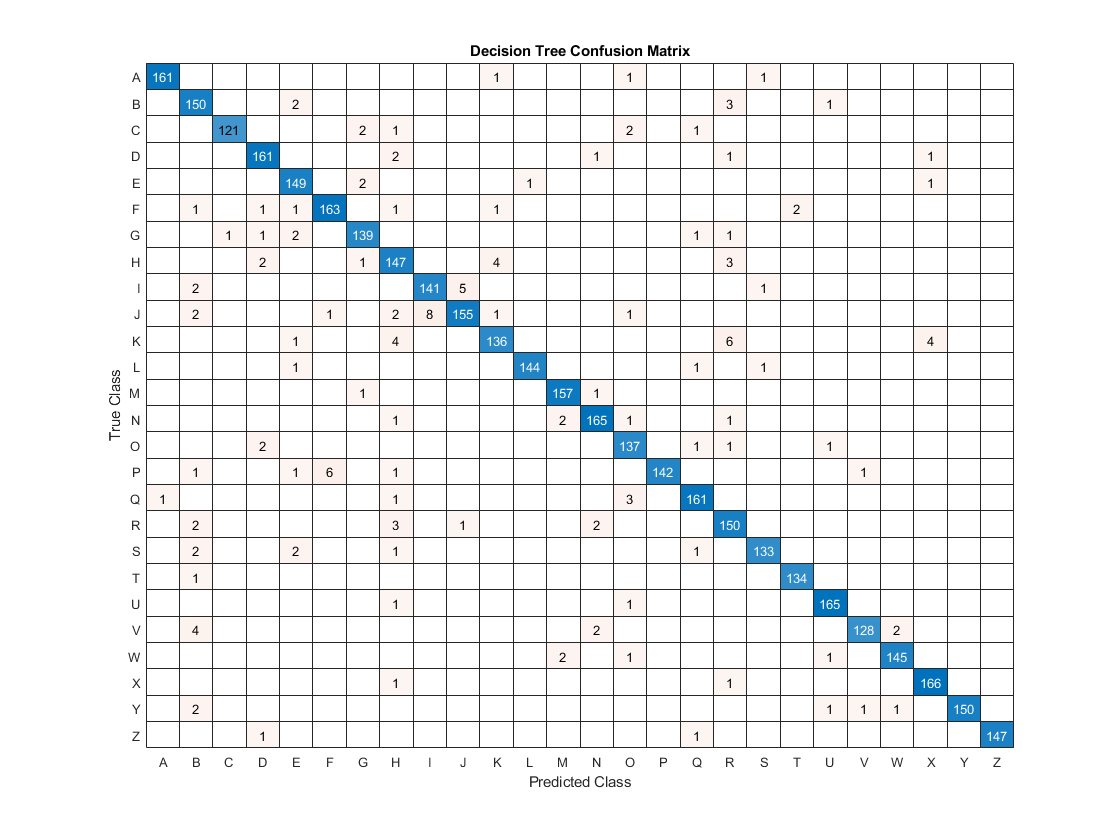

Accuracy: 0.9617 Precision: 0.9616 Recall: 0.9630 F1 0.9623. Train time: 15.1719 Predict time: 1.9844


TestRandomForest

fprintf("Done\n");

Done


### FinalModelComparison

fprintf("Running FinalModelComparison\n");

Running FinalModelComparison


  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1



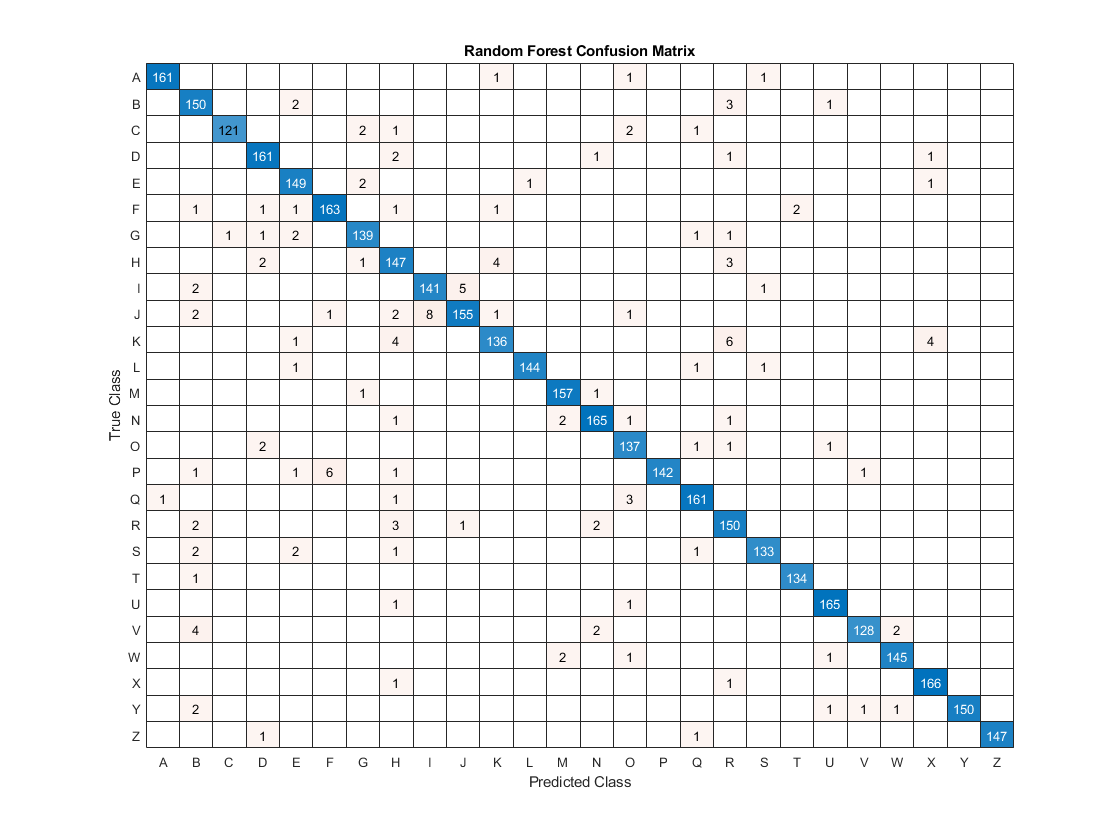

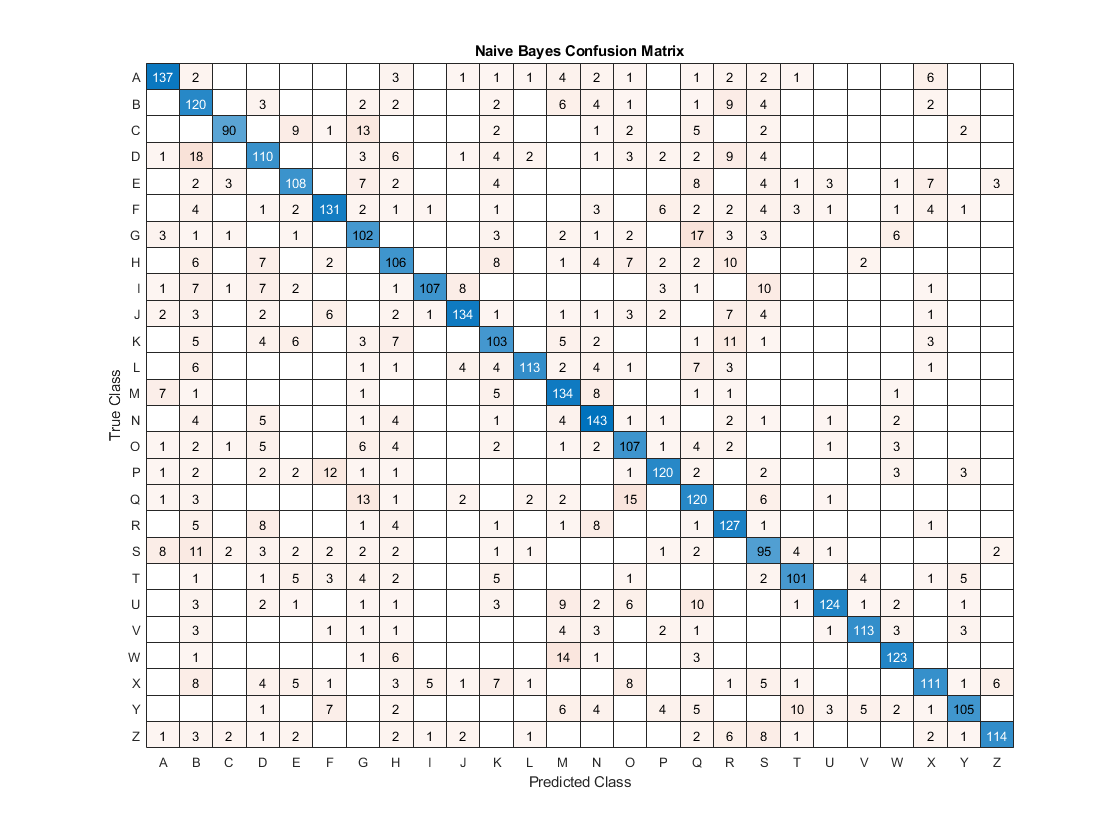

        Method         MisclassificationCount    Accuracy    Precision    Recall       F1       PredictionTime
    _______________    ______________________    ________    _________    _______    _______    ______________

    "Random Forest"              153             0.96175      0.96163     0.96303    0.96233         2.4844   
    "Naive Bayes"               1002              0.7495      0.74906     0.76753    0.75818         4.4219   
    "Decision Tree"              478              0.8805       0.8811     0.88212    0.88161       0.015625   



FinalModelComparison

fprintf("Done\n");

Done
